clear all
close all

%WORKING IN eV

v2=5e+9;
vx=1.8e+13; %18 TeV
M11=1000;
smin=0;
smax=10;
a=1.45e-9;
r1=a;
r2=a;
hxmin=0.01;
hxmax=0.1;

h2eevno=zeros(1,100);
h2euvno=zeros(1,100);
h2etvno=zeros(1,100);
h2uevno=zeros(1,100);
h2uuvno=zeros(1,100);
h2utvno=zeros(1,100);
hx1vno=zeros(1,100);
hx2vno=zeros(1,100);
hx3vno=zeros(1,100);
ssno=zeros(1,100);
m1vno=zeros(1,100);
m2vno=zeros(1,100);
m3vno=zeros(1,100);

h2eevio=zeros(1,100);
h2euvio=zeros(1,100);
h2etvio=zeros(1,100);
h2uevio=zeros(1,100);
h2uuvio=zeros(1,100);
h2utvio=zeros(1,100);
hx1vio=zeros(1,100);
hx2vio=zeros(1,100);
hx3vio=zeros(1,100);
ssio=zeros(1,100);
m1vio=zeros(1,100);
m2vio=zeros(1,100);
m3vio=zeros(1,100);

k=0;
z=0;

Mm=[M11 0 0 ; 0 M11 0 ; 0 0 M11];
tic
for i=1:50000000
    hx1=hxmin+rand*(hxmax-hxmin);
    hx2=hxmin+rand*(hxmax-hxmin);
    hx3=hxmin+rand*(hxmax-hxmin);
    h2ee=rand;
    h2eu=rand;
    h2et=rand;
    h2ue=rand;
    h2uu=rand;
    h2ut=0;
    
    mD=(v2/sqrt(2))*[h2ee h2eu h2et ; h2ue h2uu h2ut ; 0 0 0];
    MD=(vx/sqrt(2))*[hx1 0 0 ; 0 hx2 0 ; 0 0 hx3];
    
    mv=mD'*inv(MD)*Mm*inv(MD')*mD;
    
    
    [v,g]=eig(mv);
    
    eigmass=[abs(g(1,1));abs(g(2,2));abs(g(3,3))];
    mmax=max(eigmass);
    %With this i limit max value of neutrino masses to 0.1
    mmin=min(eigmass);
    if (mmax<0.1)
        
        if (eigmass(1)==mmin)
            if((mmax^2<2.9e-3) && (mmax^2>2e-3))
                
           
            s_emu=smin+rand*(smax-smin);
        
        
            Rl=[cos(s_emu*pi/180) sin(s_emu*pi/180) r1 ; -sin(s_emu*pi/180) cos(s_emu*pi/180) r2 ; -r1*cos(s_emu*pi/180)+r2*sin(s_emu*pi/180) -r2*cos(s_emu*pi/180)-r1*sin(s_emu*pi/180) 1];
            Upmns=Rl*v;
            
            %Choose only acceptable values of pmns
             if (abs(Upmns(1,1))<(0.845) && (abs(Upmns(1,1))>(0.801)))
                
                if (abs(Upmns(1,2))<(0.579) && (abs(Upmns(1,2))>(0.513)))
                    
                    if (abs(Upmns(1,3))<(0.156) && (abs(Upmns(1,3))>(0.143)))
                        
                        if (abs(Upmns(2,1))<(0.507) && (abs(Upmns(2,1))>(0.233)))
                            
                            if (abs(Upmns(2,2))<(0.694) && (abs(Upmns(2,2))>(0.461)))
                                
                                if (abs(Upmns(2,3))<(0.778) && (abs(Upmns(2,3))>(0.631)))
                                    
                                    if (abs(Upmns(3,1))<(0.526) && (abs(Upmns(3,1))>(0.261)))
                                        
                                        if (abs(Upmns(3,2))<(0.701) && (abs(Upmns(3,2))>(0.471)))
                                            
                                            if (abs(Upmns(3,3))<(0.761) && (abs(Upmns(3,3))>(0.611)))
                                                
                                                k=k+1;
                                                h2eevno(k)=h2ee;
                                                h2euvno(k)=h2eu;
                                                h2etvno(k)=h2et;
                                                h2uevno(k)=h2ue;
                                                h2uuvno(k)=h2uu;
                                                h2utvno(k)=h2ut;
                                                hx1vno(k)=hx1;
                                                hx2vno(k)=hx2;
                                                hx3vno(k)=hx3;
                                                ssno(k)=s_emu;
                                                m1vno(k)=g(1,1);
                                                m2vno(k)=g(2,2);
                                                m3vno(k)=g(3,3);
                                                
                                            end
                                        end
                                    end
                                end
                            end
                        end
                    end
                end
             end
         end
        end
        if (eigmass(3)==mmin)
            
            if ((mmin^2>7e-5) && (mmin^2<7.8e-5))

            Rl=[cos(s_emu*pi/180) sin(s_emu*pi/180) r1 ; -sin(s_emu*pi/180) cos(s_emu*pi/180) r2 ; -r1*cos(s_emu*pi/180)+r2*sin(s_emu*pi/180) -r2*cos(s_emu*pi/180)-r1*sin(s_emu*pi/180) 1];
            Upmns=Rl*v;
            
            %Choose only acceptable values of pmns
             if (abs(Upmns(1,1))<(0.845) && (abs(Upmns(1,1))>(0.801)))
                
                if (abs(Upmns(1,2))<(0.579) && (abs(Upmns(1,2))>(0.513)))
                    
                    if (abs(Upmns(1,3))<(0.156) && (abs(Upmns(1,3))>(0.143)))
                        
                        if (abs(Upmns(2,1))<(0.507) && (abs(Upmns(2,1))>(0.233)))
                            
                            if (abs(Upmns(2,2))<(0.694) && (abs(Upmns(2,2))>(0.461)))
                                
                                if (abs(Upmns(2,3))<(0.778) && (abs(Upmns(2,3))>(0.631)))
                                    
                                    if (abs(Upmns(3,1))<(0.526) && (abs(Upmns(3,1))>(0.261)))
                                        
                                        if (abs(Upmns(3,2))<(0.701) && (abs(Upmns(3,2))>(0.471)))
                                            
                                            if (abs(Upmns(3,3))<(0.761) && (abs(Upmns(3,3))>(0.611)))
                                               
                                           
                                                z=z+1;
                                                h2eevio(z)=h2ee;
                                                h2euvio(z)=h2eu;
                                                h2etvio(z)=h2et;
                                                h2uevio(z)=h2ue;
                                                h2uuvio(z)=h2uu;
                                                h2utvio(z)=h2ut;
                                                hx1vio(z)=hx1;
                                                hx2vio(z)=hx2;
                                                hx3vio(z)=hx3;
                                                ssio(z)=s_emu;
                                                m1vio(z)=g(1,1);
                                                m2vio(z)=g(2,2);
                                                m3vio(z)=g(3,3);
                                                
                                                
                                            end
                                        end
                                    end
                                end
                            end
                        end
                    end
                end
            end
        end
    end 
    end
    
end
toc

Elapsed time is 824.186058 seconds.



h2eevno

h2eevno =     0.2927    0.0552    0.0300    0.2917    0.0024    0.0478    0.5698    0.4580    0.3654    0.1093    0.0006    0.3804    0.3744    0.0641    0.0489    0.1328         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


h2euvno

h2euvno =     0.0325    0.5814    0.3359    0.0428    0.5499    0.3064    0.2215    0.1039    0.1132    0.9544    0.6981    0.0370    0.0676    0.7832    0.7342    0.7771         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


h2etvno

h2etvno =     0.7621    0.6328    0.4248    0.7215    0.9597    0.2654    0.9576    0.7914    0.5637    0.8198    0.7893    0.9149    0.6176    0.9883    0.6796    0.8927         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


h2uevno

h2uevno =     0.5845    0.4925    0.3424    0.2771    0.5331    0.0819    0.3075    0.1910    0.2126    0.1583    0.2212    0.3593    0.1756    0.2677    0.0620    0.2780         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


h2uuvno

h2uuvno =     0.9844    0.9060    0.6723    0.6481    0.8798    0.1597    0.9020    0.6168    0.6525    0.3715    0.5445    0.8979    0.8131    0.5160    0.1591    0.4460         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


h2utvno

h2utvno =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


hx1vno

hx1vno =     0.0347    0.0378    0.0236    0.0330    0.0450    0.0169    0.0536    0.0402    0.0296    0.0484    0.0433    0.0425    0.0314    0.0512    0.0398    0.0491         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


hx2vno

hx2vno =     0.0499    0.0882    0.0656    0.0316    0.0595    0.0771    0.0445    0.0269    0.0304    0.0962    0.0735    0.0428    0.0355    0.0410    0.0630    0.0614         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


hx3vno

hx3vno =     0.0845    0.0916    0.0947    0.0172    0.0430    0.0998    0.0164    0.0623    0.0798    0.0460    0.0568    0.0363    0.0809    0.0534    0.0178    0.0755         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


ssno

ssno =     0.0485    0.6521    2.7085    5.2640    0.1473    2.3059    1.3307    5.4443    2.6262    4.0404    9.8793    8.7847    8.9998    0.5015    7.7974    0.2623         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m1vno

m1vno = 	1.0e+-17 *

         0    0.0799   -0.0461         0         0   -0.0466         0         0   -0.6939    0.2844    0.0434   -0.6939    0.6939   -0.0587    0.0770   -0.0006         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m2vno

m2vno =     0.0509    0.0058    0.0062    0.0490    0.0166    0.0002    0.0472    0.0533    0.0531    0.0006    0.0029    0.0481    0.0501    0.0092    0.0003    0.0034         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


m3vno

m3vno =     0.0326    0.0448    0.0448    0.0323    0.0531    0.0452    0.0229    0.0314    0.0271    0.0533    0.0476    0.0334    0.0334    0.0533    0.0490    0.0478         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0



h2eevio

h2eevio =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


h2euvio

h2euvio =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


h2etvio

h2etvio =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


h2uevio

h2uevio =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


h2uuvio

h2uuvio =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


h2utvio

h2utvio =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


hx1vio

hx1vio =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


hx2vio

hx2vio =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


hx3vio

hx3vio =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ssio

ssio =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m1vio

m1vio =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m2vio

m2vio =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


m3vio

m3vio =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


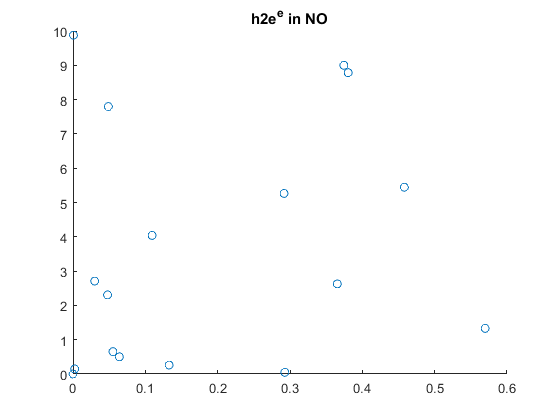


scatter(h2eevno,ssno)
title('h2e^e in NO')

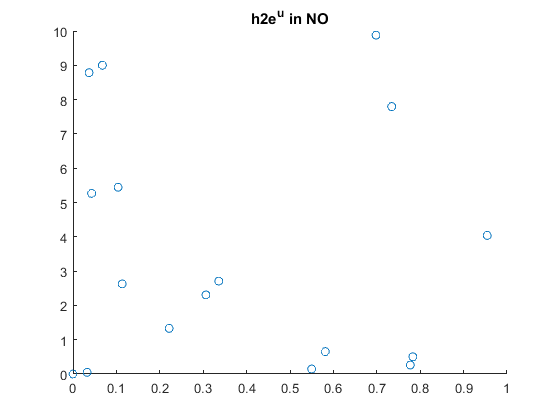


scatter(h2euvno,ssno)
title('h2e^u in NO')

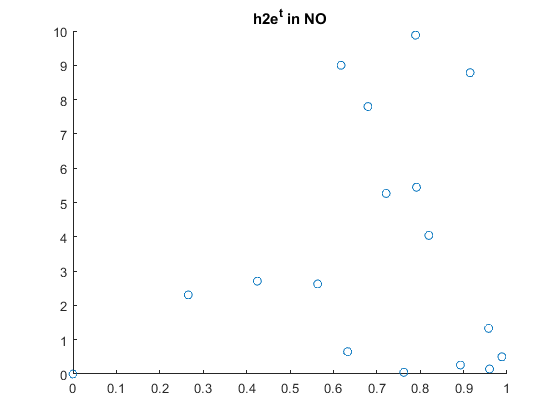


scatter(h2etvno,ssno)
title('h2e^t in NO')

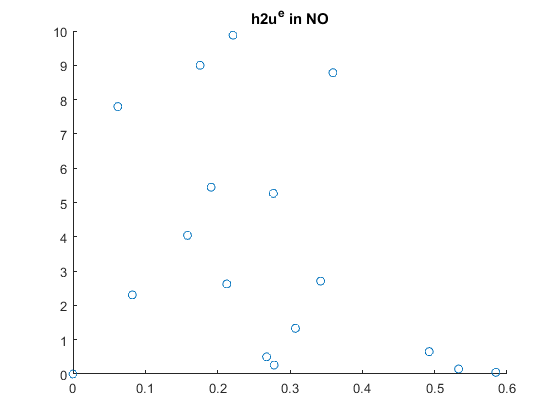


scatter(h2uevno,ssno)
title('h2u^e in NO')

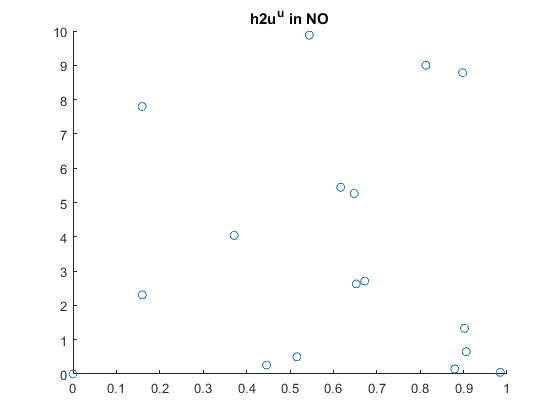


scatter(h2uuvno,ssno)
title('h2u^u in NO')

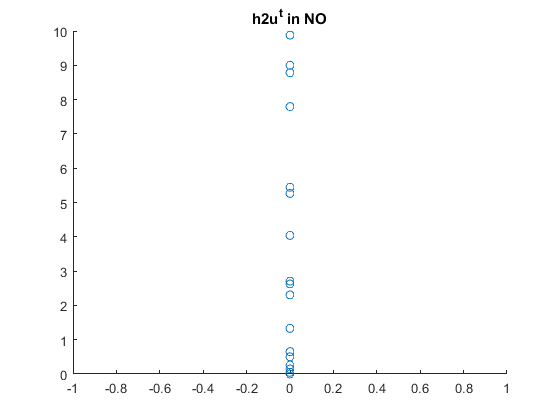


scatter(h2utvno,ssno)
title('h2u^t in NO')

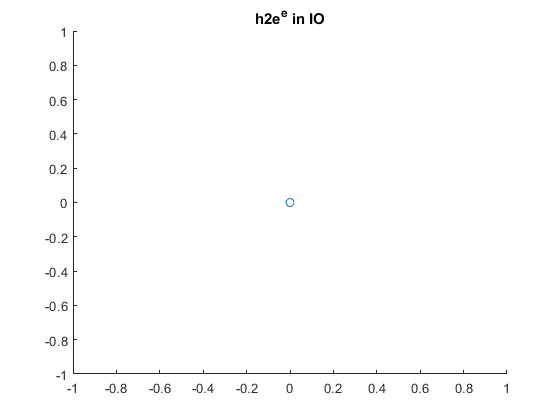



scatter(h2eevio,ssio)
title('h2e^e in IO')

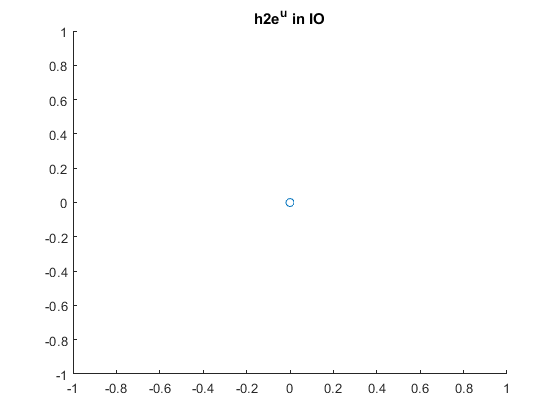


scatter(h2euvio,ssio)
title('h2e^u in IO')

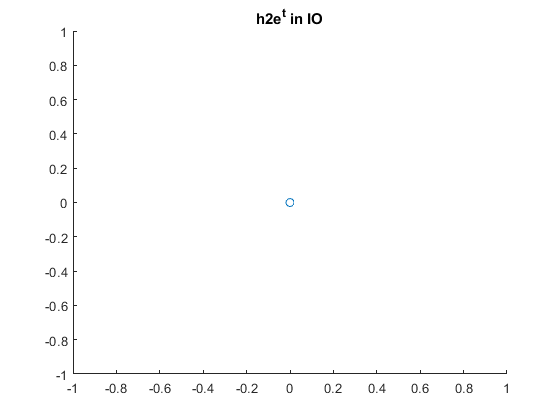


scatter(h2etvio,ssio)
title('h2e^t in IO')

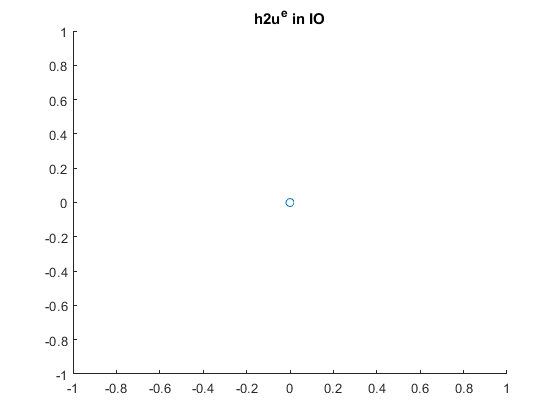


scatter(h2uevio,ssio)
title('h2u^e in IO')

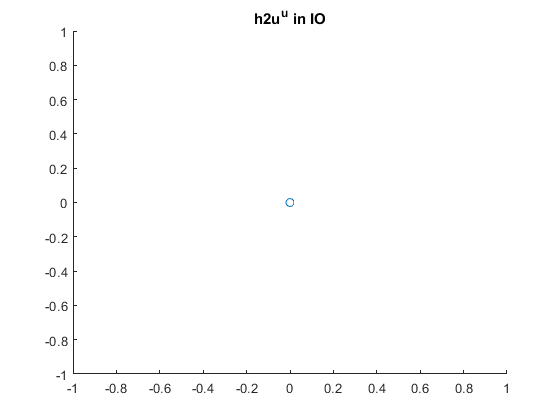


scatter(h2uuvio,ssio)
title('h2u^u in IO')

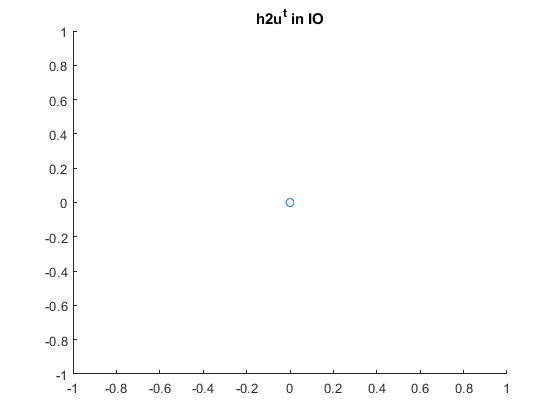


scatter(h2utvio,ssio)
title('h2u^t in IO')